# Test FD001


% Read data in
% Pseudo-time series data. Data split into units and time in cycles, which
% both are unknown entities at this point. No idea on what the measurements
% and values truly mean at this point. All data numerical


train_FD001 = readtable("train_FD001.txt");
% Data is cycles over a time per 
variables = train_FD001.Properties.VariableNames;
disp(train_FD001);

    Var1    Var2     Var3       Var4      Var5     Var6      Var7      Var8      Var9     Var10    Var11    Var12     Var13     Var14     Var15    Var16    Var17     Var18     Var19     Var20     Var21    Var22    Var23    Var24    Var25    Var26 
    ____    ____    _______    _______    ____    ______    ______    ______    ______    _____    _____    ______<

summary(train_FD001);

Variables:

    Var1: 20631×1 double

        Values:

            Min           1   
            Median       52   
            Max         100   

    Var2: 20631×1 double

        Values:

            Min           1   
            Median      104   
            Max         362   

    Var3: 20631×1 double

        Values:

            Min       -0.0087 
            Median          0 
            Max        0.0087 

    Var4: 20631×1 double

        Values:

            Min       -0.0006 
            Median          0 
            Max        0.0006 

    Var5: 20631×1 double

        Values:

            Min         100   
            Median      100   
            Max         100   

    Var6: 20631×1 double

        Values:

            Min        518.67 
            Median     518.67 
            Max        518.67 

    Var7: 20631×1 double

        Values:

    

% STD per column
for i = 1:length(variables)
    current_column = train_FD001.(variables{i});
    column_std = std(current_column);
    % Display the standard deviation
    fprintf('STD - %s: %.2f\n', variables{i}, column_std);
end

STD - Var1: 29.23
STD - Var2: 68.88
STD - Var3: 0.00
STD - Var4: 0.00
STD - Var5: 0.00
STD - Var6: 0.00
STD - Var7: 0.50
STD - Var8: 6.13
STD - Var9: 9.00
STD - Var10: 0.00
STD - Var11: 0.00
STD - Var12: 0.89
STD - Var13: 0.07
STD - Var14: 22.08
STD - Var15: 0.00
STD - Var16: 0.27
STD - Var17: 0.74
STD - Var18: 0.07
STD - Var19: 19.08
STD - Var20: 0.04
STD - Var21: 0.00
STD - Var22: 1.55
STD - Var23: 0.00
STD - Var24: 0.00
STD - Var25: 0.18
STD - Var26: 0.11



% Relative large deviations in sensor data for vars
% 14 & 19

[rows, cols] = size(train_FD001);
disp(['Rows:', num2str(rows)]);

Rows:20631


disp(['Columns: ', num2str(cols)]);

Columns: 26


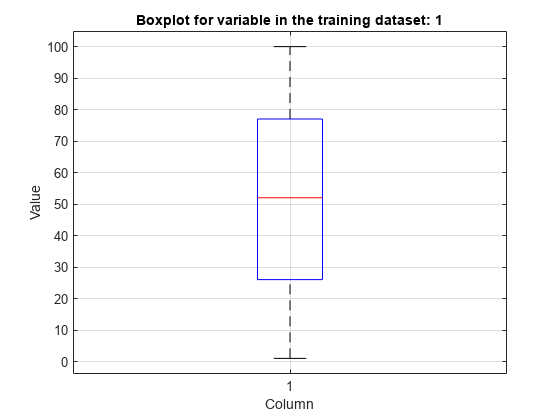

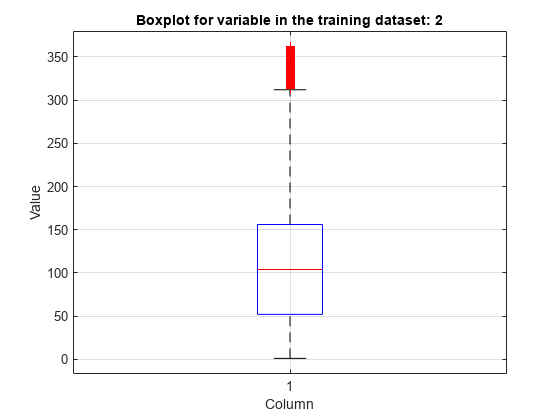

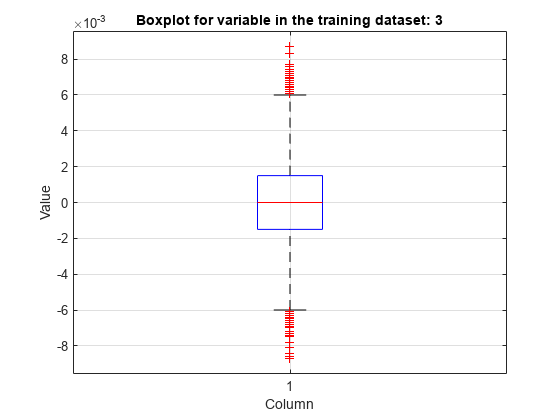

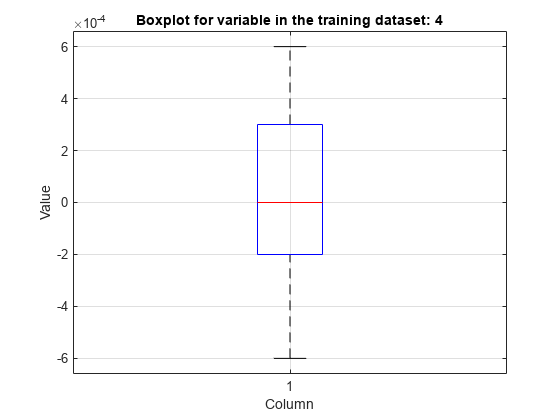

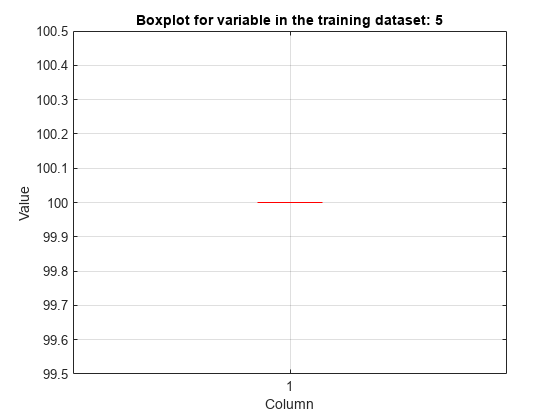

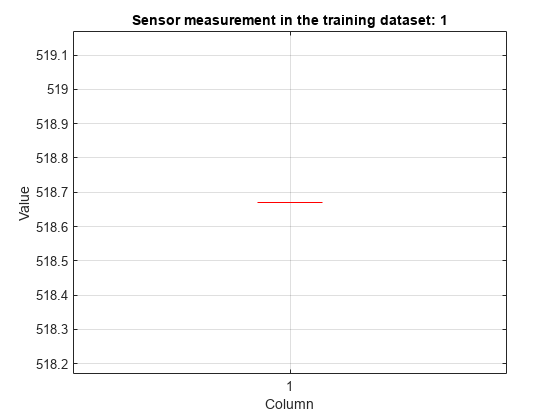

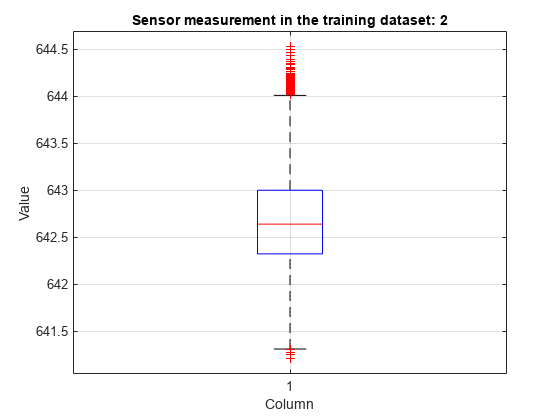

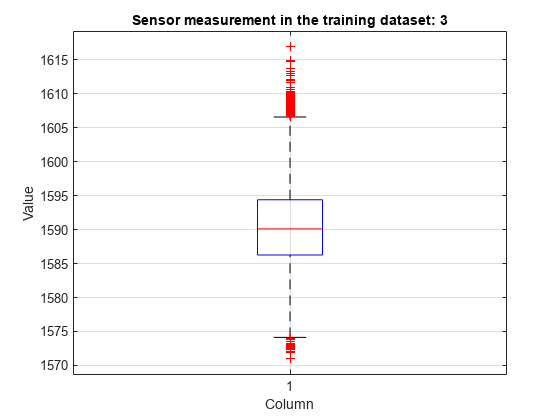

% Boxplots of variables
train_FD001_arr = table2array(train_FD001);

for i = 1:length(train_FD001.Properties.VariableNames)
    figure;
    boxplot(train_FD001.(i),'Positions',i);
    xlabel('Column');
    ylabel('Value');
    title(['Boxplot for variable in the training dataset: ', num2str(i)]);
    if i > 5
        title(['Sensor measurement in the training dataset: ', num2str(i - 5)]);
    end
    grid on;
end

## Train FD 001

% This set contains 1110 observations - Just a vector with no real link to
% the actual dataset. Unsure how to use.
% Read data in
% Pseudo-time series data. Data split into units and time in cycles, which
% both are unknown entities at this point. No idea on what the measurements
% and values truly mean at this point. All data numerical
RUL_FD001 = fileread("RUL_FD001.txt");

train_FD001 = readtable("train_FD001.txt");
% Data is cycles over a time per 
variables = train_FD001.Properties.VariableNames;
% View that data import worked correctly
disp(train_FD001);

    Var1    Var2     Var3       Var4      Var5     Var6      Var7      Var8      Var9     Var10    Var11    Var12     Var13     Var14     Var15    Var16    Var17     Var18     Var19     Var20     Var21    Var22    Var23    Var24    Var25    Var26 
    ____    ____    _______    _______    ____    ______    ______    ______    ______    _____    _____    ______<

summary(train_FD001);

Variables:

    Var1: 20631×1 double

        Values:

            Min           1   
            Median       52   
            Max         100   

    Var2: 20631×1 double

        Values:

            Min           1   
            Median      104   
            Max         362   

    Var3: 20631×1 double

        Values:

            Min       -0.0087 
            Median          0 
            Max        0.0087 

    Var4: 20631×1 double

        Values:

            Min       -0.0006 
            Median          0 
            Max        0.0006 

    Var5: 20631×1 double

        Values:

            Min         100   
            Median      100   
            Max         100   

    Var6: 20631×1 double

        Values:

            Min        518.67 
            Median     518.67 
            Max        518.67 

    Var7: 20631×1 double

        Values:

    

% STD per column
std_of_columns =std(train_FD001);

disp(std_of_columns);

     Var1      Var2       Var3          Var4       Var5       Var6        Var7       Var8      Var9       Var10       Var11       Var12      Var13      Var14       Var15        Var16      Var17      Var18      Var19      Var20        Var21       Var22     Var23    Var24     Var25      Var26 
    ______    ______    _________    __________    ____    __________    _______    ______    ______    

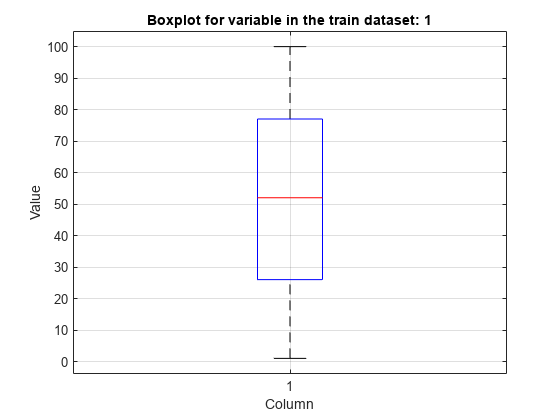

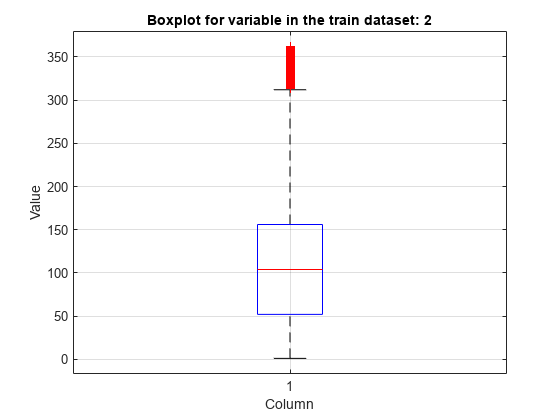

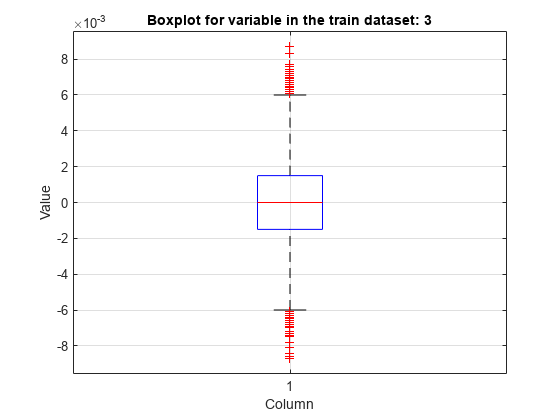

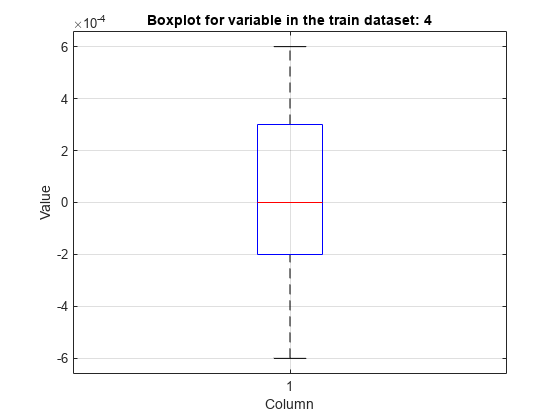

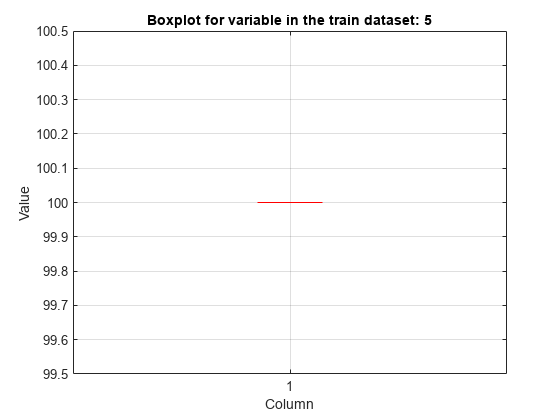

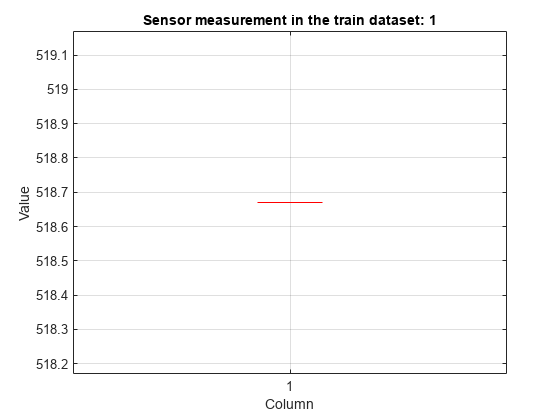

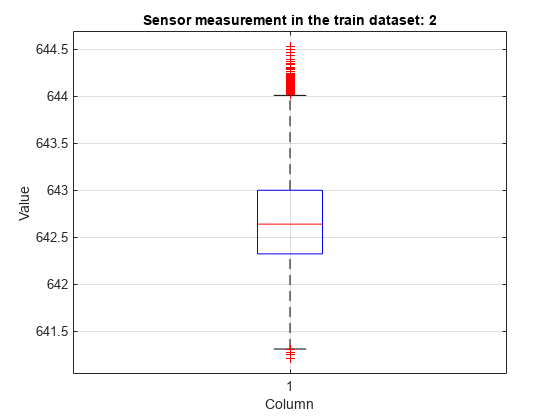

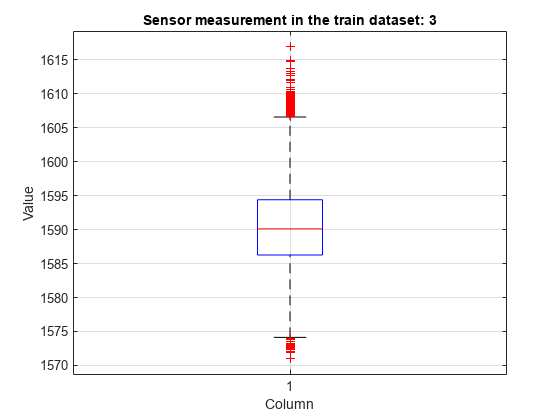

% Boxplots of variables
for i = 1:length(train_FD001.Properties.VariableNames)
    figure;
    boxplot(train_FD001.(i),'Positions',i);
    xlabel('Column');
    ylabel('Value');
    title(['Boxplot for variable in the train dataset: ', num2str(i)]);
    if i > 5
        title(['Sensor measurement in the train dataset: ', num2str(i - 5)]);
    end
    grid on;
end

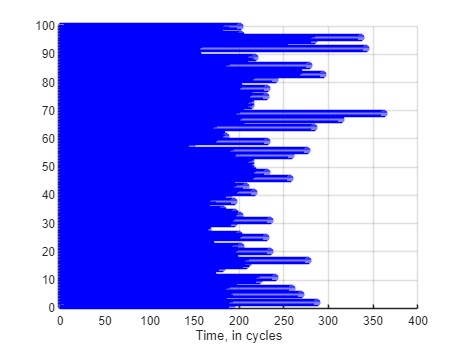

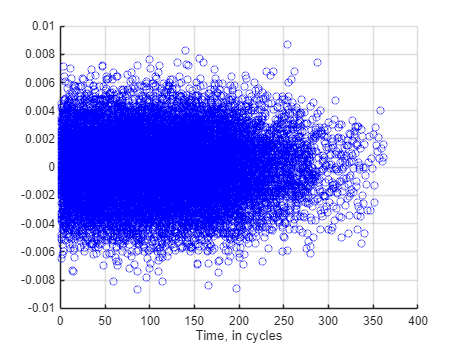

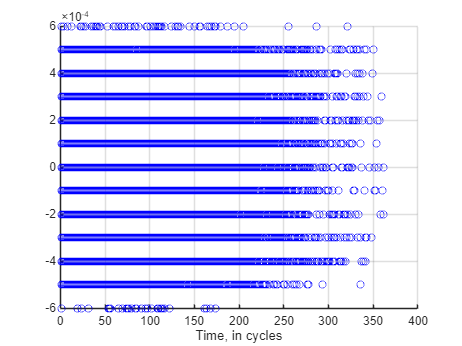

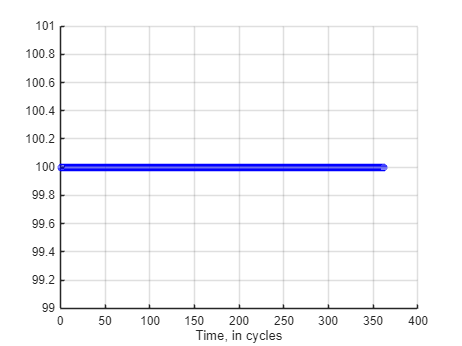

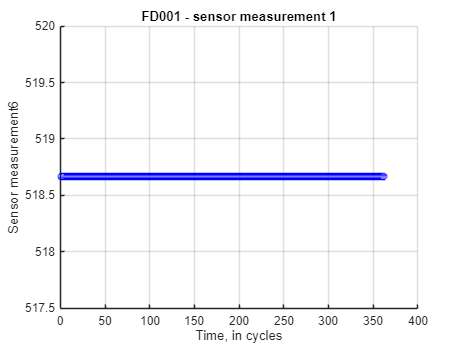

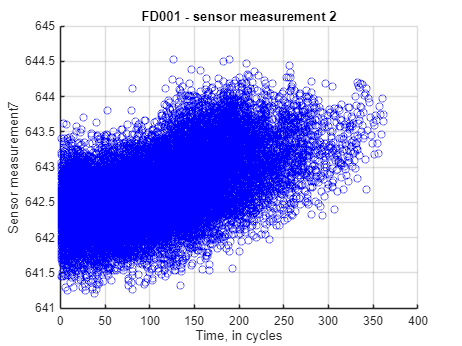

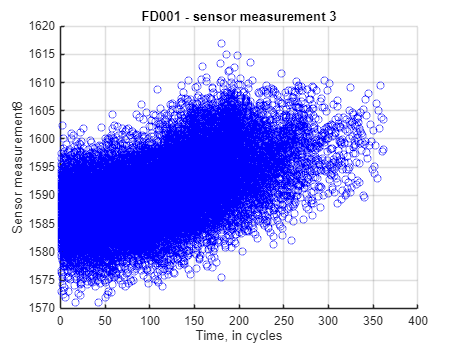

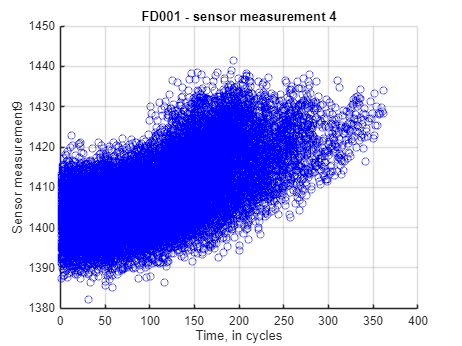

% Scatter out all data
for i = 1:length(train_FD001.Properties.VariableNames)
    if i == 2
        continue
    end
    col_name =  ['Var', num2str(i)];
    figure;
    scatter(train_FD001.Var2,train_FD001.(col_name), 'blue');
    xlabel('Time, in cycles');
    grid on;
    if i > 5
       ylabel(['Sensor measurement', num2str(i)]);
       title(['FD001 - sensor measurement ', num2str(i -5)]);
    end
end